% k = -100:100;
% hold on;
% plot(k, h(-k));
% plot(k, h(k-50));
% hold off;

% a = 0.9;
% a = 0.95;
a = 0.99;
% a = 0.998;

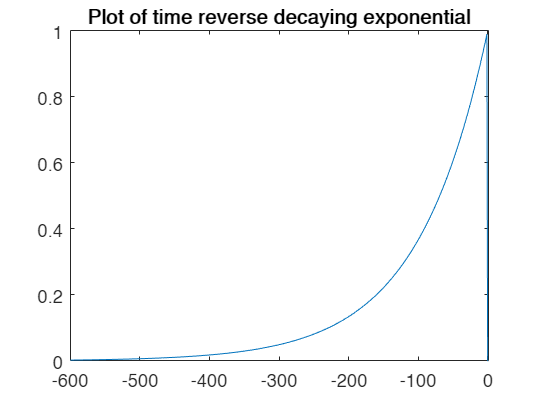

% n = -100:80; % for a=0.90
% n = -200:80; % for a=0.95
n = -600:1; % for a=0.99
g = conv(a.^(-n) .* h(-n), a.^(-n) .* h(-n), 'full');
% soundsc(g);
figure;
plot(n, a.^(-n) .* h(-n));
title('Plot of time reverse decaying exponential')

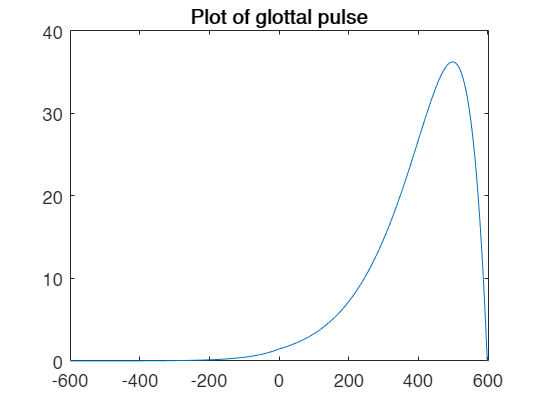

figure;
n2 = -600:602;
plot(n2, g);
title('Plot of glottal pulse')

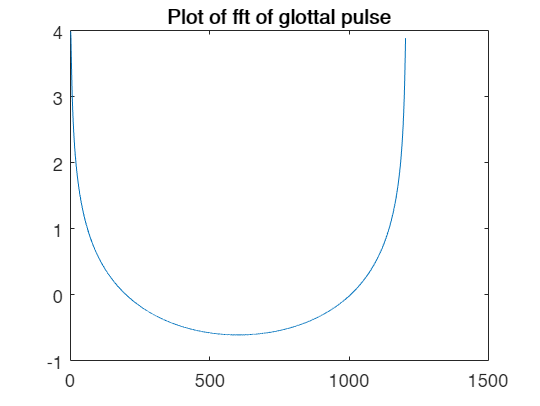

f = fft(g);
figure;
plot(log10(abs(f)));
title('Plot of fft of glottal pulse')

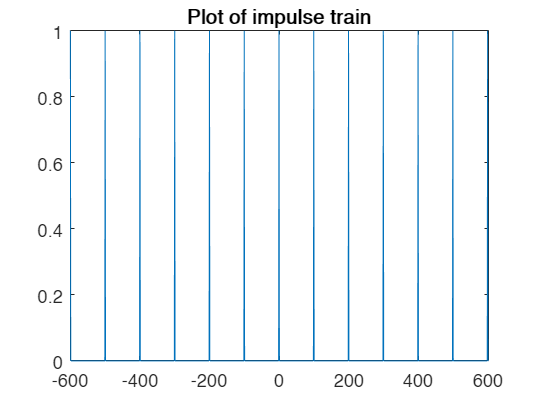

f1 = 100;
f2 = 200;
fs = 10000;
y1 = zeros(size(n2));
y1(mod(n2, f1) == 0) = 1;
figure;
plot(n2,y1);
title('Plot of impulse train')

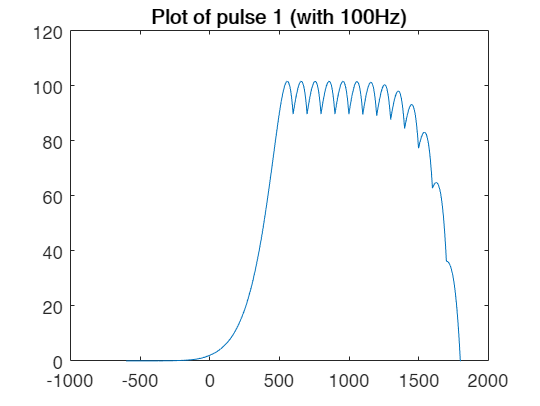

pulse1 = conv(y1, g, 'full');
length(pulse1);
soundsc(pulse1);
figure;
plot(-600:1804, pulse1);
title('Plot of pulse 1 (with 100Hz)')

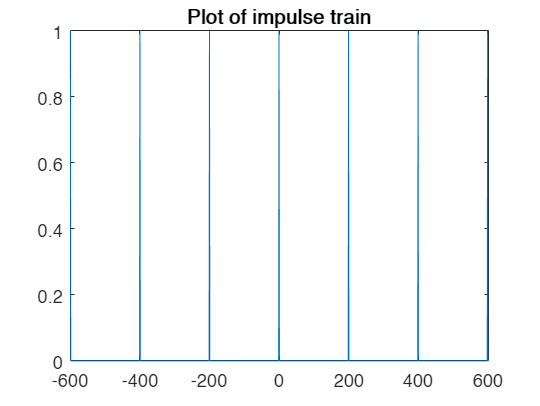

y2 = zeros(size(n2));
y2(mod(n2, f2) == 0) = 1;
figure;
plot(n2,y2);
title('Plot of impulse train');

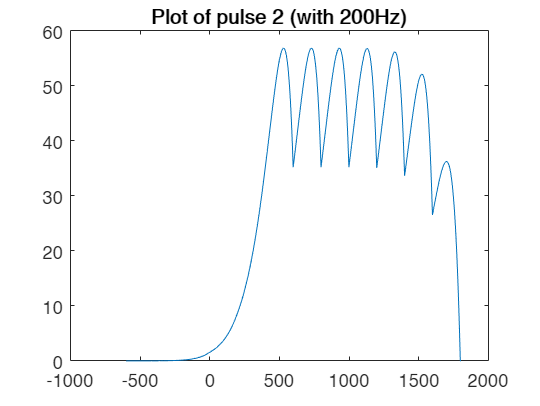

pulse2 = conv(y2, g, 'full');
length(pulse2);
soundsc(pulse2);
figure;
plot(-600:1804, pulse2);
title('Plot of pulse 2 (with 200Hz)')

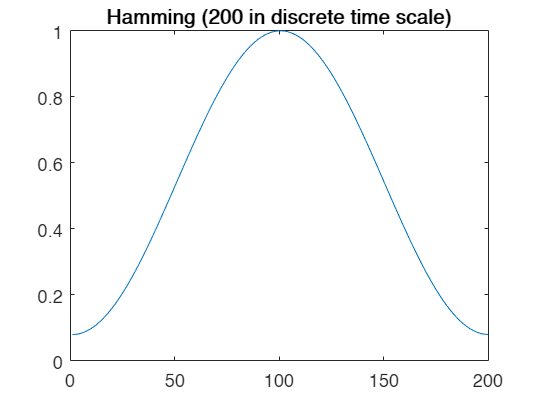

hamming_len = 0.02*fs;
ham = hamming(hamming_len, "symmetric");
figure;
plot(ham);
title('Hamming (200 in discrete time scale)')

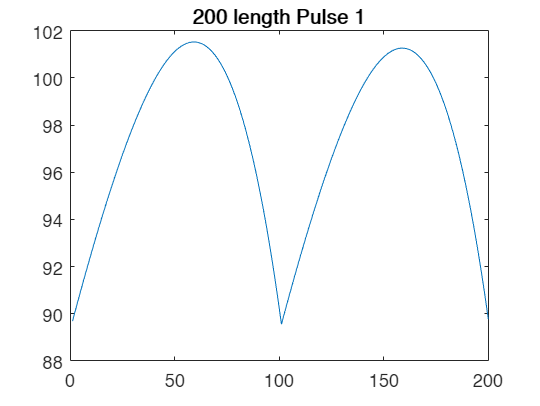

window1 = (ham' .* pulse1(1600:1799));
figure;
plot(pulse1(1600:1799))
title('200 length Pulse 1')

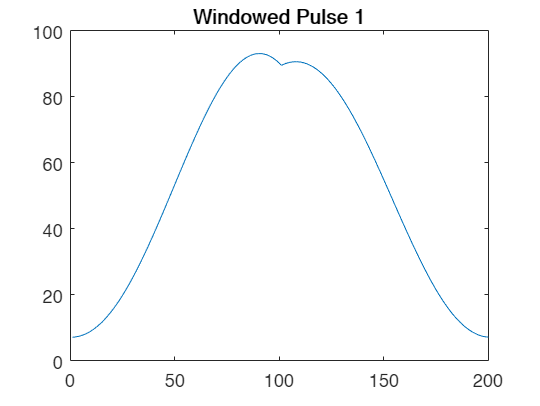

figure;
plot(window1)
title('Windowed Pulse 1')

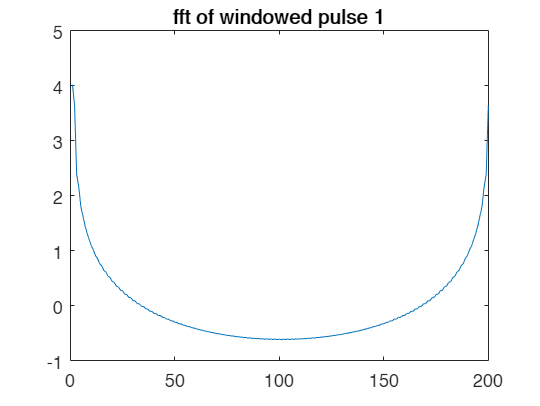

fwindow1 = fft(window1);
figure;
plot(log10(abs(fwindow1)))
title('fft of windowed pulse 1')

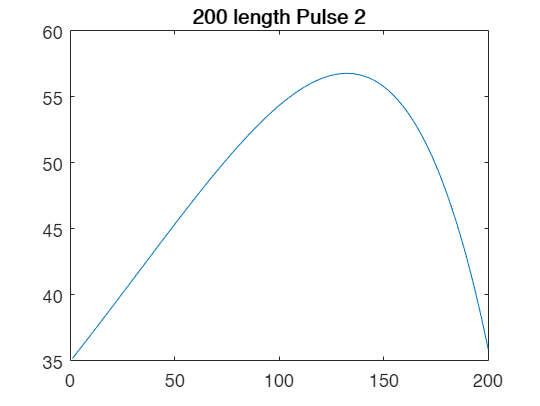

window2 = (ham' .* pulse2(1600:1799));
figure;
plot(pulse2(1600:1799))
title('200 length Pulse 2')

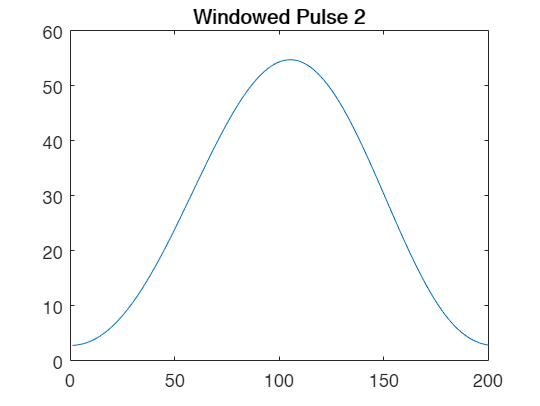

figure;
plot(window2)
title('Windowed Pulse 2')

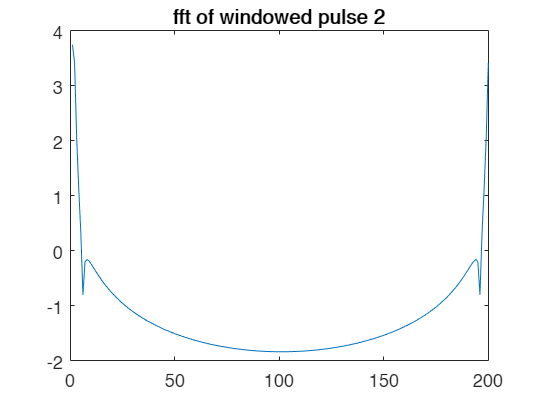

fwindow2 = fft(window2);
figure;
plot(log10(abs(fwindow2)))
title('fft of windowed pulse 2')

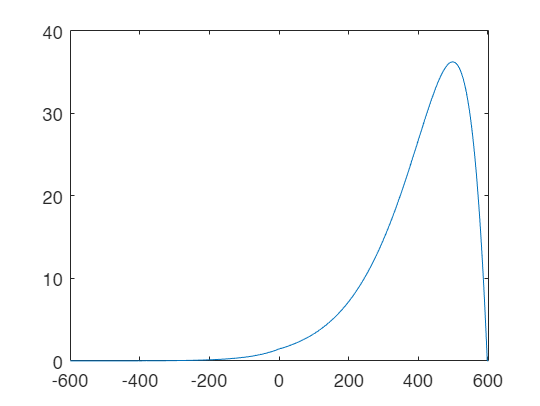

plot(n2, g)

% Now for a glottal pulse to be more rounded off,
a = 0.998;
n = -2500:1;
n2 = -2500:2502;
gNew = conv(a.^(-n) .* h(-n), a.^(-n) .* h(-n), 'full');
length(gNew)

ans = 5003

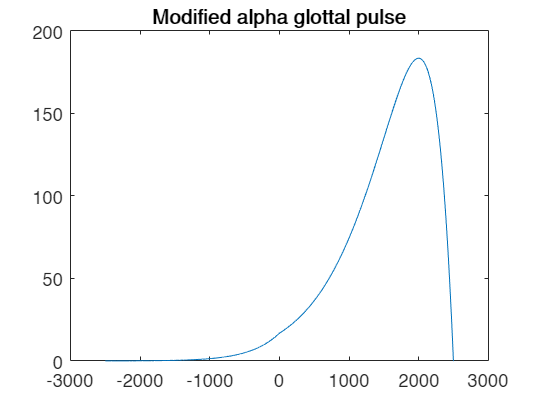

figure;
plot(n2, gNew)
title('Modified alpha glottal pulse')

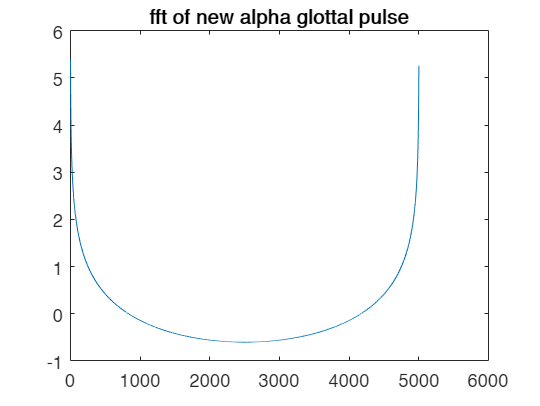

fgNew = fft(gNew);
figure;
plot(log10(abs(fgNew)))
title('fft of new alpha glottal pulse')

soundsc(gNew)

soundsc(g)